# **STEP_04:**  Explore a simple cantilever - **RESONANCE excitation test**

Let's get familiar with the Flexible Beam block in Simscape Multibody

- [https://www.mathworks.com/help/releases/R2026a/sm/ref/flexiblerectangularbeam.html](https://www.mathworks.com/help/releases/R2026a/sm/ref/flexiblerectangularbeam.html)

And what better way, than to model and VERIFY the behavior of a simple cantilever beam 

**Objective:**

- Excite the cantilever model (Simscape Multibody) at it's resonant frequencies and observe it's response

**Some comments about the Simulation:**

- The CANTILEVER

- We've represented the cantilever using 2 flexible body blocks

- EXCITATION:

- We apply a purely sinusoidal load

- The user can select an excitation frequency that corresponds to a resonance frequency

- The excitation FORCE is applied **at a point 1/4 along the length** of the beam (from the wall) 

So here is the Cantilever system that we're going to focus on - and note the orientation of the **Inertial reference frame**.

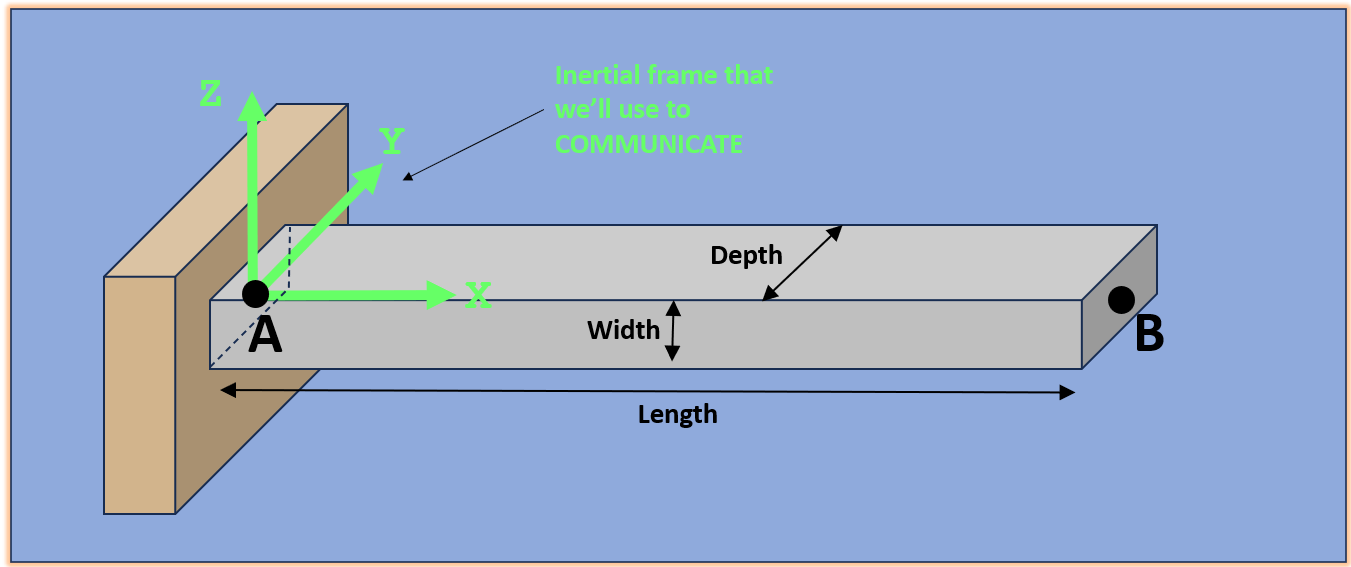

## Clear the workspace

clear

## Define the BEAM (we'll eventually call it a COLUMN)

Define the beam's cross section.  See:

- [`bh_create_column_OBJ`](matlab:  edit  bh_create_column_OBJ)

- [`bh_flex_column_CLS`](matlab: edit bh_flex_column_CLS)

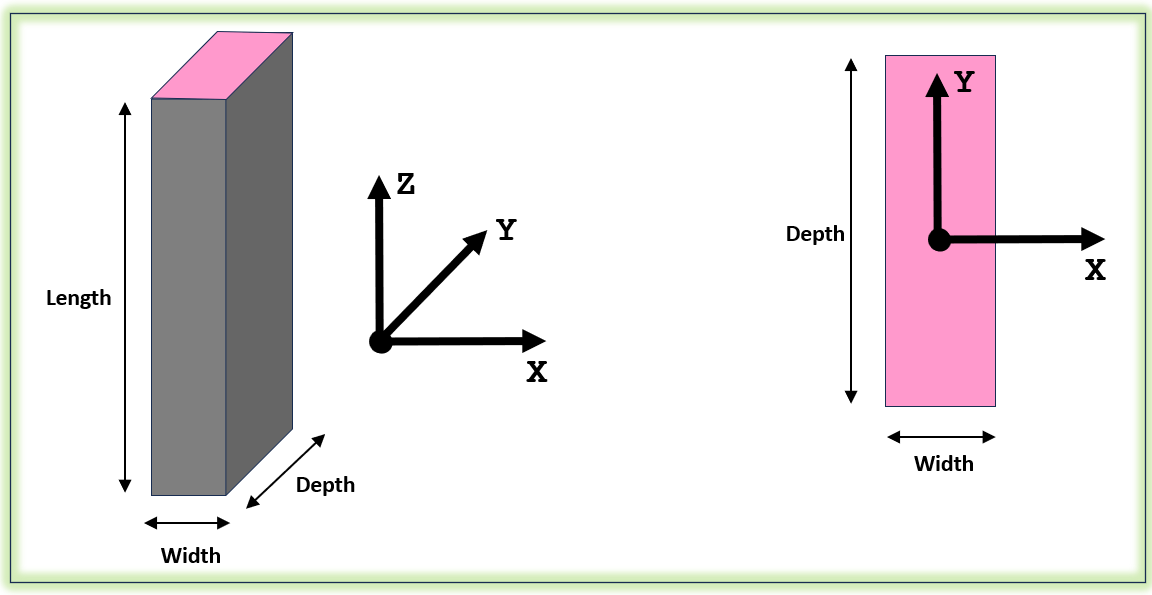

col_OBJ              = bh_create_column_OBJ(Width=1/1000, Depth=25.4/1000, Length=300/1000, density=7800);
col_OBJ.damp_K_coeff = 1e-4; 
col_OBJ.num_eles     = 5;

So what attributes do we have

col_OBJ

col_OBJ =   bh_flex_column_CLS with properties:

          WIDTH_x: 1.0000e-03
          DEPTH_y: 0.0254
         LENGTH_z: 0.3000
          density: 7800
      E_GPa_Young: 200
        v_Poisson: 0.3000
     damp_M_coeff: 0
     damp_K_coeff: 1.0000e-04
       damp_ratio: 0
         num_eles: 5
    num_ret_modes: 5
          BC_case: "FIXED_FIXED_WITH_SWAY"
             mass: 0.0594
              vol: 7.6200e-06
               Ix: 1.3656e-09
               Iy: 2.1167e-12
               Kx: 188.1481
             area: 2.5400e-05


## Define the Environment

g_vector = [0, 0, -9.80665];

## Bending Modes

For a Cantilever beam, the **analytical frequencies** of transverse vibration can be derived and are tabulated in most introductory texts on Mechanical vibrations - e.g.: see

-    Rao, S., "Mechanical Vibrations, 2nd Edition", Addison Wesley, 1990

The first 4 transverse natural frequencies are:

my_E    = col_OBJ.E_GPa_Young*1e9; % (Pa)
my_I    = col_OBJ.Iy;
my_dens = col_OBJ.density;
my_A    = col_OBJ.WIDTH_x * col_OBJ.DEPTH_y;
my_L    = col_OBJ.LENGTH_z;

ana.Bl_sq = [(1.875104^2), (4.694091^2), (7.854757^2), (10.995541^2)];
ana.wn    = ana.Bl_sq * sqrt((my_E*my_I)/(my_A*my_dens*my_L^4));  % (rad/sec)
ana.fn    = ana.wn / (2*pi);  % (Hz)

ana

ana = struct with fields:
    Bl_sq: [3.5160 22.0345 61.6972 120.9019]
       wn: [57.1065 357.8801 1.0021e+03 1.9637e+03]
       fn: [9.0888 56.9584 159.4851 312.5273]


And the SHAPES of these modes are:

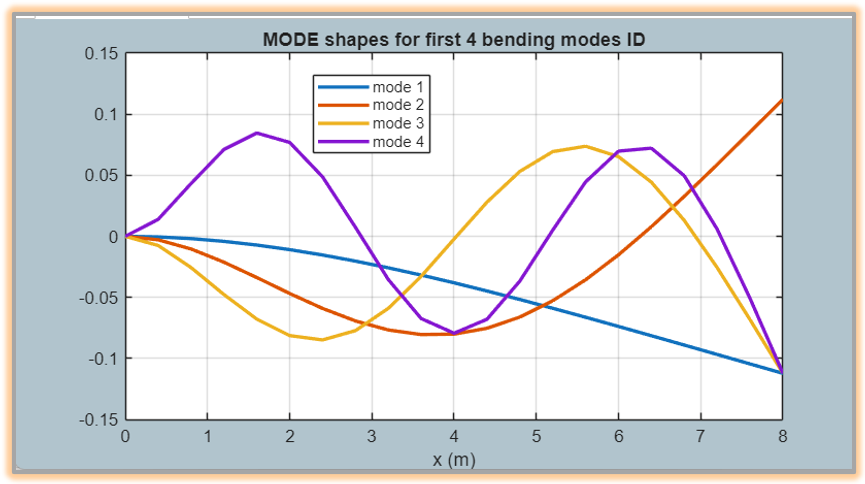

## Now compare against the Simulink model

open_system("bh_cantilever_RESONANCE_test.slx")

When the Simulink model opens:

- Go to the `APPLIED_LOAD_SYS` system

- Choose a Mode to excite

- Run the Simulation ... and observe the Beam response in the **Multibody Explorer** viewer